# Wind Support to Bird migration

**Raphaël Nussbaumer, Baptiste Schmid, Felix Liechti**

October 20th, 2020

## Abstract

[...]

- Bird airspeed has a significant influence on energy depletion and consequently on survival of migrant bird. In a context of climatique change, understanding how bird navigate in the air is essential (use of windspeed, altitude, spring vs autumn)

- In this study, we examine the airspeed chosen by bird using 30+ weather radar in Western Europe collected over a full year.

- Althgouh large variation on groundspeed were recorded, birds fly at a relative constant airspeed between season, altitude and region because the difference is due to windspeed.

## Introduction

How do bird compensate for wind?

- strengh and direction of wind

- prefered direction

- altitude

- time/season

- timing of deparute: are bird compensating more early in the night?

- (- specie of bird, size)

## Methods

**Weather radar data: bird vector speed and density**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ref) and processed as explained in Nussbaumer (2020) ([https://doi.org/10.1101/2020.10.13.321844](https://doi.org/10.1101/2020.10.13.321844)). The final dataset consisting of bird density (ρ) [bird/km^3], flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo [https://zenodo.org/record/3610185.](https://zenodo.org/record/3610185.)

**Climate Reanalaysis: Wind vector speed at pressure level**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind are downloaed from the ERA5 reanalysis (ref) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). Both components (`U` and `V`) are linearly interpolated (time-space 4D) at each datapoint of the weather radar data. 

load('../2018/data/dc_corr.mat','dc');
NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

We recompute the ground speed similarly to Nussbaumer (2020) but uses the non-interpolated speeds because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to the most only original data. 

for i_d=1:numel(dc)
    
    % Compute the n/s and e/w componenent of the flight speed
    dc(i_d).u = dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0° is north and 90° is west. -> u is east (+) - west (-)
    dc(i_d).v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-)

    % Remove data not cleaned for density (e.g. rain). 
    id = isnan(dc(i_d).dens3) | dc(i_d).dens3==0;
    dc(i_d).u(id)=nan;
    dc(i_d).v(id)=nan;

    coef=8-2.4;
    cc = dc(i_d).insect.*coef;
    
    airspeed_u = dc(i_d).u-dc(i_d).windu;
    airspeed_v = dc(i_d).v-dc(i_d).windv;
    
    v_adc = sqrt((dc(i_d).u-dc(i_d).windu).^2 + (dc(i_d).v-dc(i_d).windv).^2);
    
    dc(i_d).u2 = airspeed_u.*(cc+v_adc)./v_adc + dc(i_d).windu;
    dc(i_d).v2 = airspeed_v.*(cc+v_adc)./v_adc + dc(i_d).windv;
end

**Ground and air speed**

Birds' groundspeed ($V_g$) and airspeed ($V_a$) can be computed respectively with


$$V_g =\sqrt{u^2 +v^2 }$$


and

 $V_a =\sqrt{{\left(u-U\right)}^2 +{\left(v-V\right)}^2 }$.

v_a=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc)); v_g=v_a; dens = v_a; v_w =v_a; sd_vvp = v_a;
for i_d=1:numel(dc)
    v_g(:,:,i_d) = sqrt(dc(i_d).u2.^2 + dc(i_d).v2.^2); % ground speed
    v_a(:,:,i_d) = sqrt((dc(i_d).u2-dc(i_d).windu).^2 +(dc(i_d).v2-dc(i_d).windv).^2); % air speed
    v_w (:,:,i_d) = sqrt(dc(i_d).windu.^2 + dc(i_d).windv.^2); % wind speed
    dens(:,:,i_d) = dc(i_d).dens4;
    sd_vvp(:,:,i_d) = dc(i_d).sd_vvp;
end

Define area (France and Germany) and season: Early spring (March), Late spring (April), Early autumn (august-september) and late autumn (October)

id_sp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-May-2018');
id_esp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-April-2018');
id_lsp = dc(1).time>datetime('1-April-2018') & dc(1).time<datetime('1-May-2018');
id_au = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Nov-2018');
id_eau = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Oct-2018');
id_lau = dc(1).time>datetime('1-Oct-2018') & dc(1).time<datetime('1-Nov-2018');
id_de = [false; true(15,1); false(21,1)]; %repmat(permute(id_de,[3,2,1]),size(v_g,1),size(v_g,2),1);
id_fr = [false(16,1); true(19,1); false(3,1)]; %repmat(permute(id_fr,[3,2,1]),size(v_g,1),size(v_g,2),1);

## Results

**Overall trend**

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

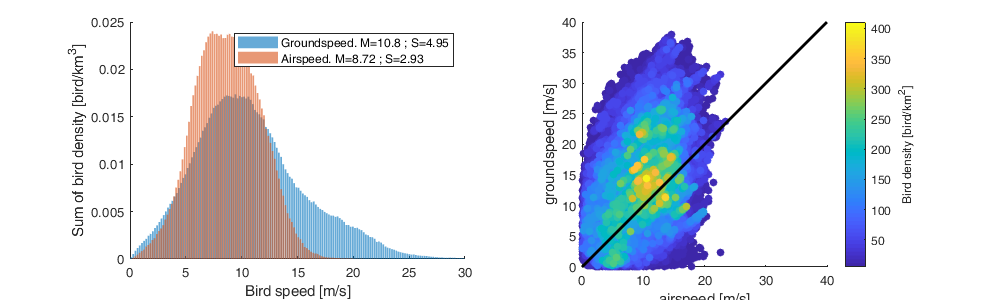

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g, dens);
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a, dens);
bar(e,h,'FaceAlpha',0.6);
%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel('Bird speed [m/s]');
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(1,2,2); hold on;
[~, id] = sort(dens(:)); id2 = id(dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(v_a(id2),v_g(id2),[],dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2)
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; c.Label.String='Bird density [bird/km^2]';

Histograms of airspeed and ground speed are normalized by the density of bird, that is, each bin of bird speed is multiply not by the number of occuruance in the dataset but by the sum of all bird density flying at this speed. 

(a) Bird move at around 11 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.7m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

**Difference in Season**

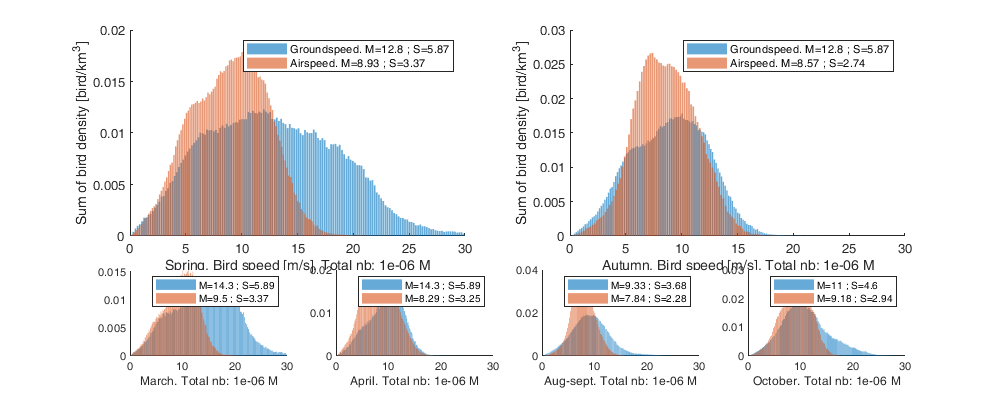

figure('position',[0 0 1000 400]);

subplot(3,2,[1 3]); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,:),dens(id_sp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,:),dens(id_sp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Spring. Bird speed [m/s]. Total nb: ' num2str(sum(dens(id_sp,:,:))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(3,2,[2 4]); hold on;
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,:),dens(id_au,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Autumn. Bird speed [m/s]. Total nb: ' num2str(sum(dens(id_au,:,:))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(3,4,9); hold on
[e,h,Mg,Sg] = histvdens(v_g(id_esp,:,:),dens(id_esp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_esp,:,:),dens(id_esp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['March. Total nb: ' num2str(sum(dens(id_esp,:,:))/1000000,3) ' M']);xlim([0 30]);

subplot(3,4,10); hold on;
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_lsp,:,:),dens(id_lsp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['April. Total nb: ' num2str(sum(dens(id_lsp,:,:))/1000000,3) ' M']); xlim([0 30]);

subplot(3,4,11); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_eau,:,:),dens(id_eau,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_eau,:,:),dens(id_eau,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Aug-sept. Total nb: ' num2str(sum(dens(id_eau,:,:))/1000000,3) ' M']); xlim([0 30]);

subplot(3,4,12); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_lau,:,:),dens(id_lau,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_lau,:,:),dens(id_lau,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['October. Total nb: ' num2str(sum(dens(id_lau,:,:))/1000000,3) ' M']); xlim([0 30]);

While the bird are moving with quite different ground speed (blue) regime in Spring (left) and Autumn (right), their actual airspeed (red) is impresively similar. Note that the total number of bird measured is very different in spring (7.88M bird/km3) and autumn (19.8M bird/km3). This is because spring is shorter, thus less measurement and it doesn't represent the actual number of bird flying through. 

## Difference between France and Germany

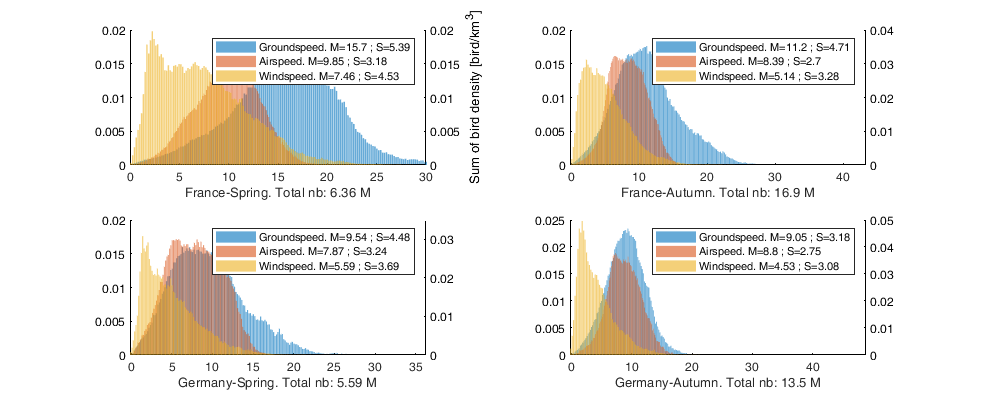

figure('position',[0 0 1000 400]);

subplot(2,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_fr),dens(id_sp,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['France-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_fr),3)))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(2,2,2); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_fr),dens(id_au,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['France-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_fr),3)))/1000000,3) ' M']);

subplot(2,2,3); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_de),dens(id_sp,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Germany-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_de),3)))/1000000,3) ' M']);

subplot(2,2,4); 
hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Germany-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_de),3)))/1000000,3) ' M']);

In this figure, we seperate both in term of region: France (top) and Germany (bottom) and Season: Spring (left) and Autumn (right). We also added the windspeed in yellow to help explain the difference between France and Germany.

Groundspeed is suprinsigly much higher in the radar in France, particularly in Spring (15.7 m/s vs 9.5 for Germany). However, airspeed is much more similar between France and Germany (9m/s vs 8.5 m/s for Germany). This difference in groundspeed uniquely is well explained by the windspeed (yellow). Indeed, in France birds benefit from a better wind speed (6m/s vs 5m/s germany) allowing them to increase their groundspeed. 

Note that this windspeed is the norm of the vector and not a projection on the prefered direction of migration. However, it is normalized by the number of bird in the air, thus the windspeed is representative of the wind support of bird migration. 

Is this a pattern unique to 2018?

More figures are plotted in Supplementary material down the page. 

**Variation with Altitude**

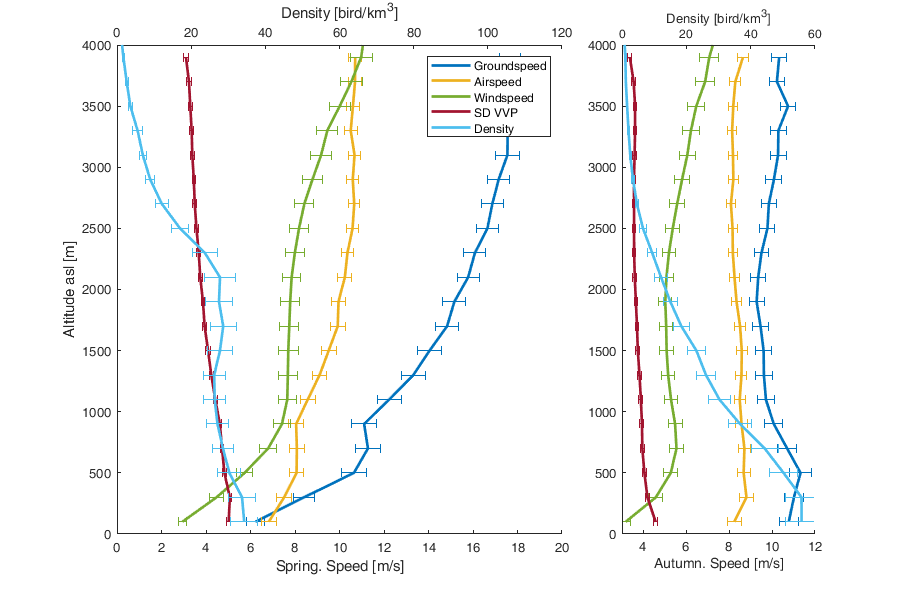

Mg = nan(numel(dc(1).alt),2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_au,i_a,:),dens(id_au,i_a,:));
end

figure('position',[0 0 900 600]);
subplot(1,3,[1 2]); hold on;
tmp = errorbar(Mg(:,1),dc(1).alt,Sg(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,1),dc(1).alt,Sa(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,1),dc(1).alt,Sw(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,1),dc(1).alt,Ss(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
xlim([0 20]);ylabel('Altitude asl [m]'); xlabel('Spring. Speed [m/s]'); ylim([0 4000]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,1),dc(1).alt,Sd(:,1)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 120]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(1,3,3); hold on;
tmp = errorbar(Mg(:,2),dc(1).alt,Sg(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,2),dc(1).alt,Sa(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,2),dc(1).alt,Sw(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,2),dc(1).alt,Ss(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([3 12]); xlabel('Autumn. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,2),dc(1).alt,Sd(:,2)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 60])

Thick line represent the mean and the error bird the 1 standard deviation computed at each altitude bin and weighted by the density of bird. `sd_vvp` is the variance of groundspeed within the bin. The size of the Spring and Autumn subplot are scaled to have the same axis scale. 

Ground speed generally increase with altitude, but airspeed increase much less as windspeed explain in great part the increase of groundspeed. This effect is visible in both spring and autumn. The profile of groundspeed and windspeed matches well in both season, making the airspeed profile relatively straight (at least in comparison to windspeed and groundspeed). 

The decrease of `sd_vvp` with altitude indicates a more directional flow of bird in high altitude (less variance in groundspeed). This variability is certainly explained by bird flying in more diverse direction at low elevation and consequently reducing the average ground speed (and airspeed!) of the bin as measure by weather radar. One could try to argue that the "angle" (derivative with regard to altitude) in sd_vvp and airspeed are matching (e.g. 100-500m bin in autumn).

**Progress of night**

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_sp',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_a),dens(id_a));
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_au',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_a),dens(id_a));
end

Undefined function or variable 'NNT'.


figure('position',[0 0 900 800]);
subplot(2,1,1); hold on;
tmp = errorbar(mida, Mg(:,1),Sg(:,1)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,1),Sa(:,1)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,1),Sw(:,1)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,1),Ss(:,1)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,1),'-','Color',tmp.Color,'LineWidth',2); 
ylim([3 14]);ylabel('Altitude asl [m]'); ylabel('Spring. Speed [m/s]'); xlim([-1 1]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,1),Sd(:,1)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,1),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(2,1,2); hold on;
tmp = errorbar(mida, Mg(:,2),Sg(:,2)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,2),Sa(:,2)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,2),Sw(:,2)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,2),Ss(:,2)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,2),'-','Color',tmp.Color,'LineWidth',2);
ylim([3 14]); ylabel('Autumn. Speed [m/s]'); xlim([-1 1]); xlabel('NNT Progress of Night (-1: Sunset | 1: Sunrise)');
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,2),Sd(:,2)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,2),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]); ylim([0 50]); 

We use the NNT which normalize the time between sunset and sunrise between -1 and 1. Both Windspeed and Groundspeed slightly increase in the first hours of the night in Spring maintining the airspeed at a relative constant speed. In autumn, there seems to be an increase of airspeed in thos same hours because groundspeed remains constant while windspeed reduces slightly. The sd_vvp seems to remains relatively constant throughout the night although increase early morning probably due to the start of diunarl movement contamination. 

# Supplementary Material

## 1. Difference France Germany

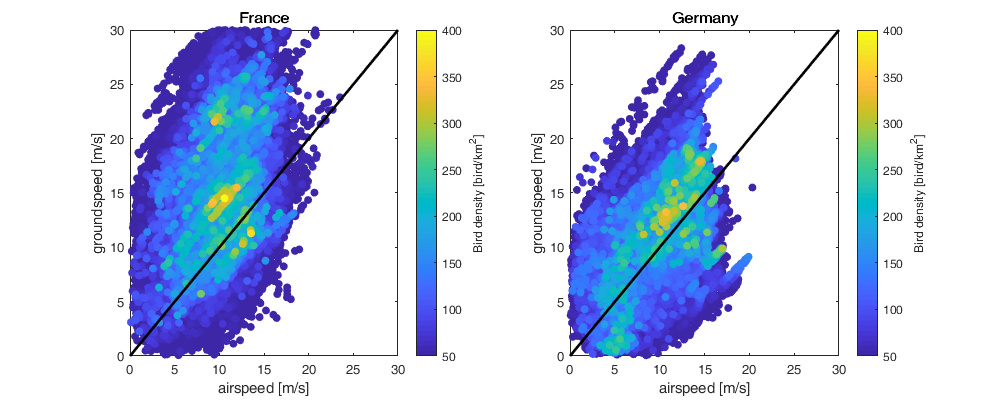

figure('position',[0 0 1000 400]);

subplot(1,2,1); hold on;
tmp = [reshape(v_a(:,:,id_fr),[],1) reshape(v_g(:,:,id_fr),[],1) reshape(dens(:,:,id_fr),[],1)];
tmp(tmp(:,3)<20,:)=[];% only keep density >5bird/km^2 for computing reason
[~,id]=sort(tmp(:,3));
scatter(tmp(id,1),tmp(id,2),[],tmp(id,3),'filled'); 
plot([0 30],[0 30],'k','LineWidth',2);
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; caxis([50 400]); c.Label.String='Bird density [bird/km^2]';
title('France'); box on; ylim([0 30]); xlim([0 30]);

subplot(1,2,2); hold on;
tmp = [reshape(v_a(:,:,id_de),[],1) reshape(v_g(:,:,id_de),[],1) reshape(dens(:,:,id_de),[],1)];
tmp(tmp(:,3)<20,:)=[];% only keep density >5bird/km^2 for computing reason
[~,id]=sort(tmp(:,3));
scatter(tmp(id,1),tmp(id,2),[],tmp(id,3),'filled'); 
plot([0 30],[0 30],'k','LineWidth',2)
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; caxis([50 400]); c.Label.String='Bird density [bird/km^2]';
title('Germany'); box on; ylim([0 30]); xlim([0 30]);

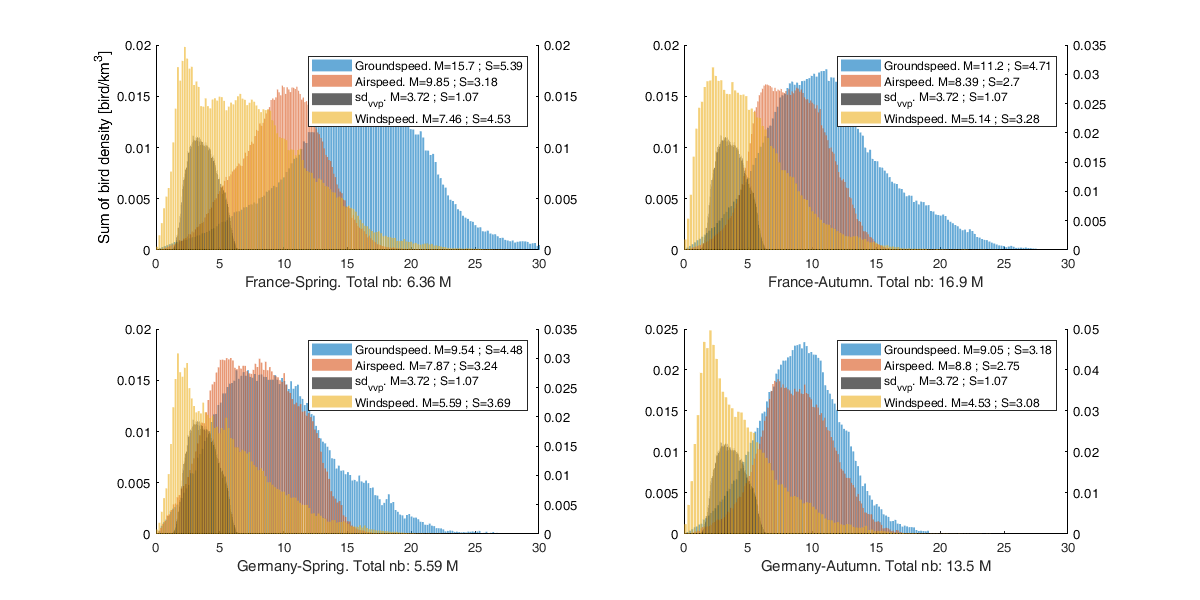

figure('position',[0 0 1200 600]);

subplot(2,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_fr),dens(id_sp,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend; xlabel(['France-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_fr),3)))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(2,2,2); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_fr),dens(id_au,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['France-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_fr),3)))/1000000,3) ' M']);

subplot(2,2,3); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_de),dens(id_sp,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['Germany-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_de),3)))/1000000,3) ' M']);

subplot(2,2,4); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; xlim([0 30])
xlabel(['Germany-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_de),3)))/1000000,3) ' M']);  legend

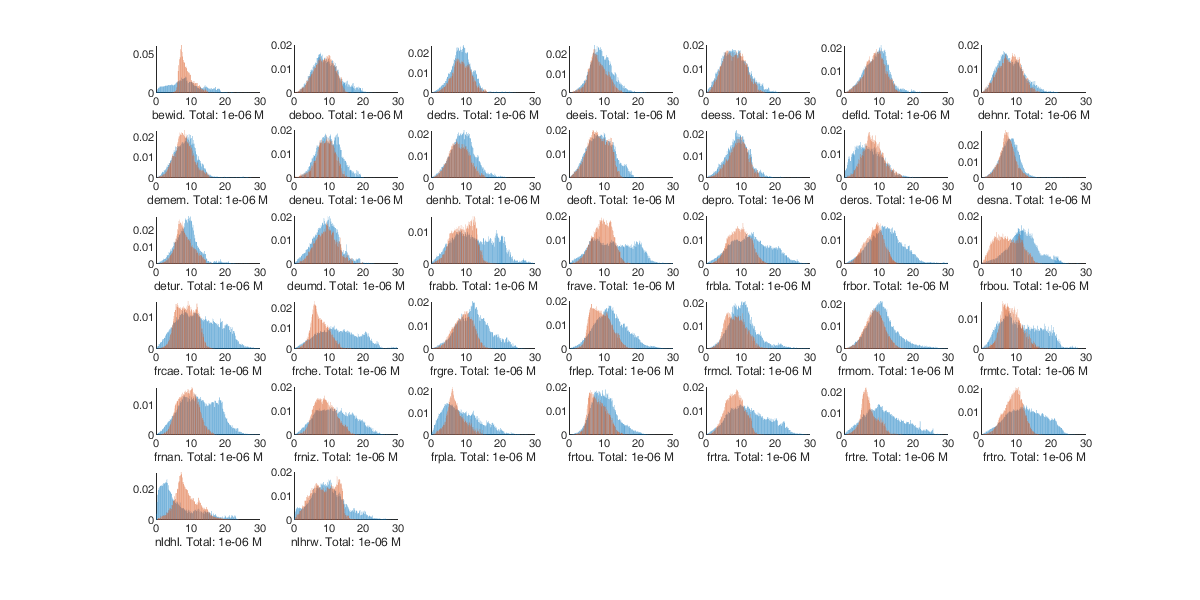

figure('position',[0 0 1200 600]);
Mg=nan(1,numel(dc));Sg=Mg;Ma=Mg;Sa=Mg;
for i_d= 1:numel(dc)
    subplot(6,7,i_d); hold on
    [e,h,Mg(i_d), Sg(i_d)] = histvdens(v_g(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma(i_d), Sa(i_d)] = histvdens(v_a(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    % legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ dc(i_d).name '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

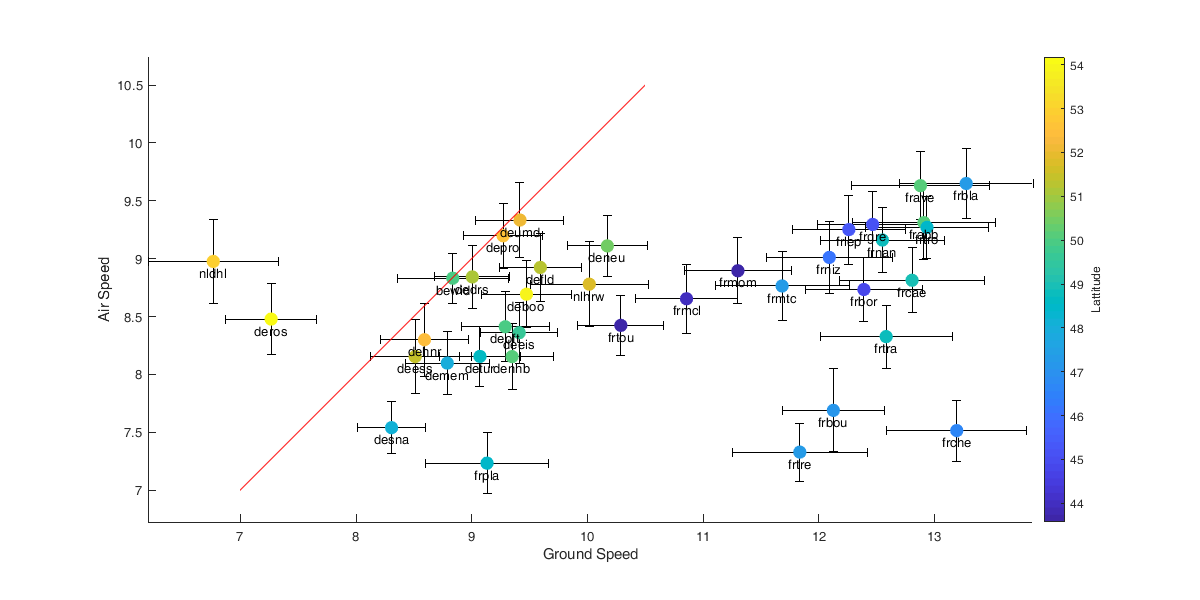

figure('position',[0 0 1200 600]); hold on;
eb(1) = errorbar(Mg,Ma,Sg/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg,Ma,Sa/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg,Ma,100,[dc.lat],'filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg,Ma-0.1,{dc.name},'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude';

There is a very strong difference visible at the country level. In Germany, the difference between airspeed and ground speed is very small while in French, the pattern observed earlier is most consistant.

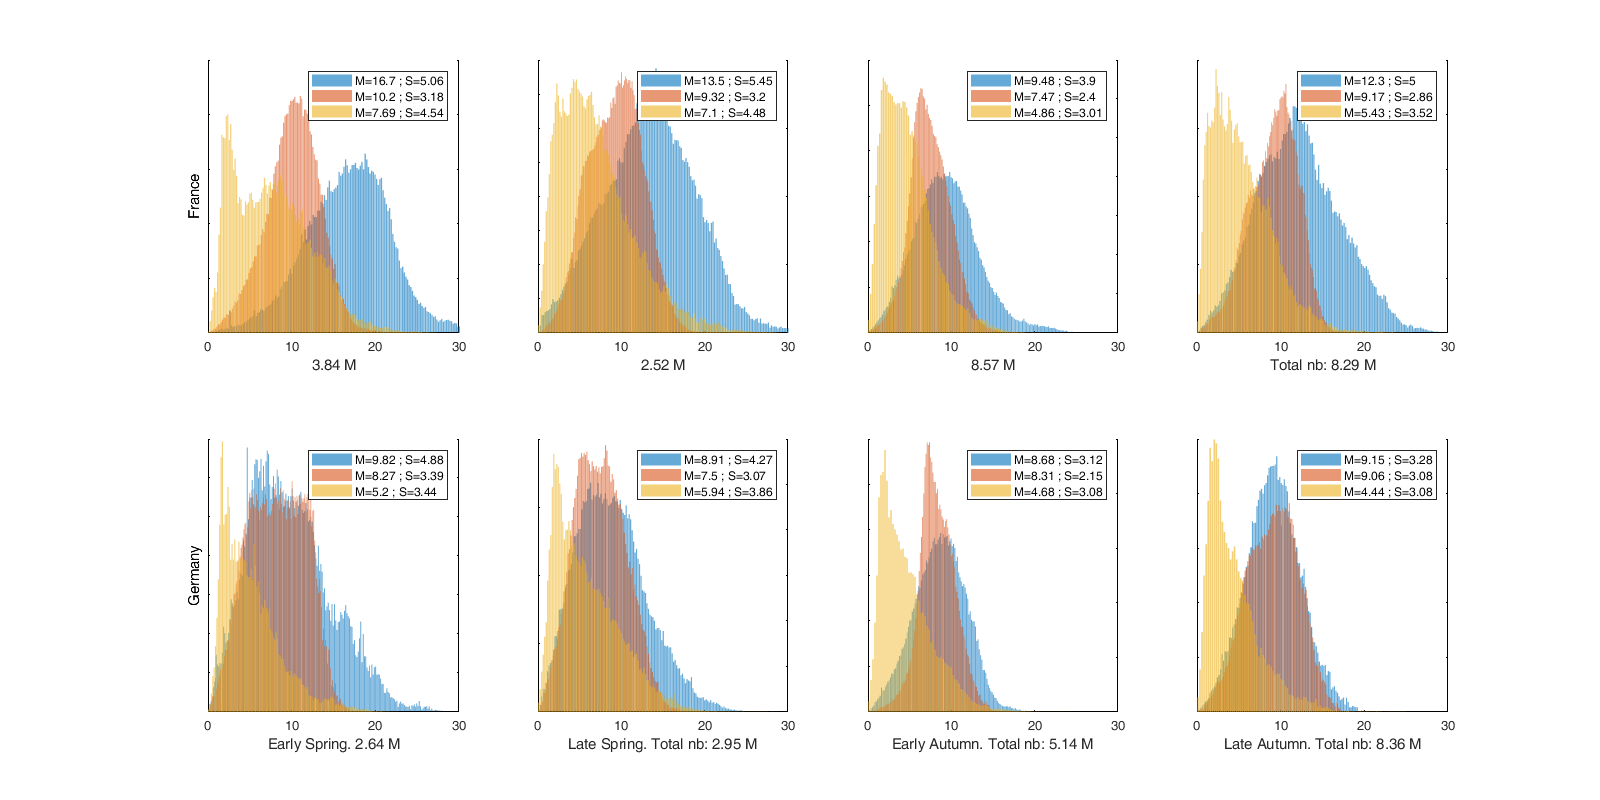

figure('position',[0 0 1600 800]);

subplot(2,4,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_esp,:,id_fr),dens(id_esp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_esp,:,id_fr),dens(id_esp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_esp,:,id_fr),dens(id_esp,:,id_fr));
ax = gca; set(ax,'yticklabel',[]); ylabel('France'); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel([num2str(nansum(nansum(nansum(dens(id_esp,:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]); 

subplot(2,4,2); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_lsp,:,id_fr),dens(id_lsp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_lsp,:,id_fr),dens(id_lsp,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_lsp,:,id_fr),dens(id_lsp,:,id_fr));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel([num2str(nansum(nansum(nansum(dens(id_lsp,:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]);

subplot(2,4,3); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_eau,:,id_fr),dens(id_eau,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_eau,:,id_fr),dens(id_eau,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_eau,:,id_fr),dens(id_eau,:,id_fr));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel([num2str(nansum(nansum(nansum(dens(id_eau,:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]);

subplot(2,4,4); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_lau,:,id_fr),dens(id_lau,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_lau,:,id_fr),dens(id_lau,:,id_fr));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_lau,:,id_fr),dens(id_lau,:,id_fr));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_lau,:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]);

subplot(2,4,5); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_esp,:,id_de),dens(id_esp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_esp,:,id_de),dens(id_esp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_esp,:,id_de),dens(id_esp,:,id_de));
ax = gca; set(ax,'yticklabel',[]); ylabel('Germany'); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Early Spring. ' num2str(nansum(nansum(nansum(dens(id_esp,:,id_de),3)))/1000000,3) ' M']);xlim([0 30]); 

subplot(2,4,6); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_lsp,:,id_de),dens(id_lsp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_lsp,:,id_de),dens(id_lsp,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_lsp,:,id_de),dens(id_lsp,:,id_de));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Late Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_lsp,:,id_de),3)))/1000000,3) ' M']);xlim([0 30]);

subplot(2,4,7); 
hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_eau,:,id_de),dens(id_eau,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_eau,:,id_de),dens(id_eau,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_eau,:,id_de),dens(id_eau,:,id_de));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Early Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_eau,:,id_de),3)))/1000000,3) ' M']);xlim([0 30]);

subplot(2,4,8); 
hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_lau,:,id_de),dens(id_lau,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a(id_lau,:,id_de),dens(id_lau,:,id_de));
bar(e,h,'FaceAlpha',0.6);
[e,h,Mw,Sw] = histvdens(v_w(id_lau,:,id_de),dens(id_lau,:,id_de));
ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
xlabel(['Late Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_lau,:,id_de),3)))/1000000,3) ' M']);xlim([0 30]);

## 2. Variation with altitude

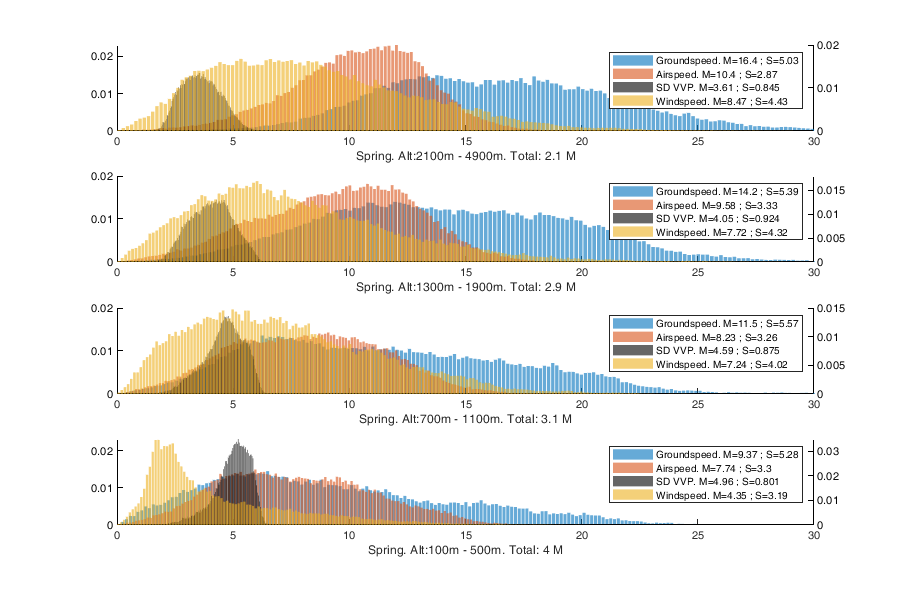

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Mw,Sw] = histvdens(v_w(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis right; bar(e,h,'FaceAlpha',0.6);
    [e,h, Ms, Ss ] = histvdens(sd_vvp(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis left; bar(e,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Spring. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_sp,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

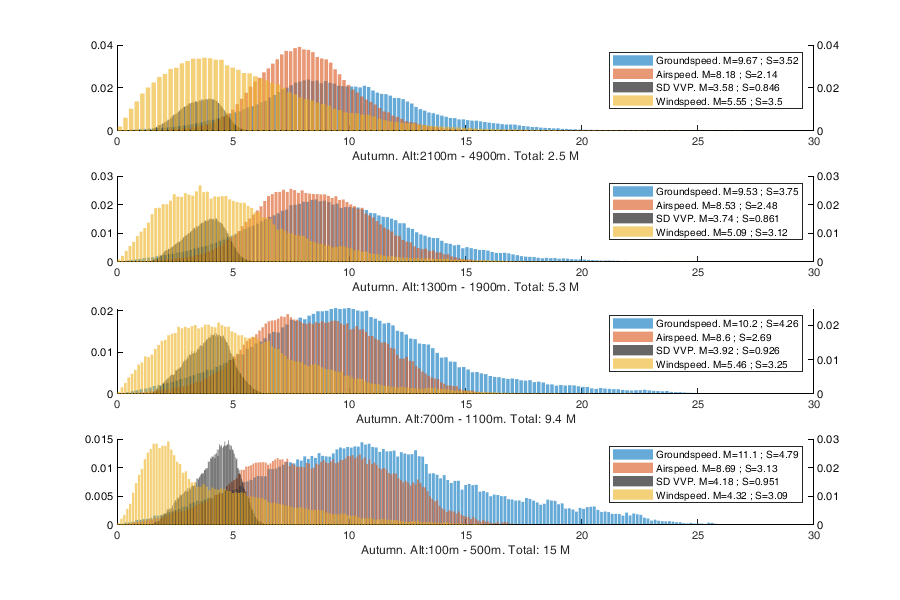

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_au,id_a,:),dens(id_au,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_au,id_a,:),dens(id_au,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Mw,Sw] = histvdens(v_w(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis right; bar(e,h,'FaceAlpha',0.6);
    [e,h, Ms, Ss] = histvdens(sd_vvp(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis left; bar(e,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Autumn. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_au,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

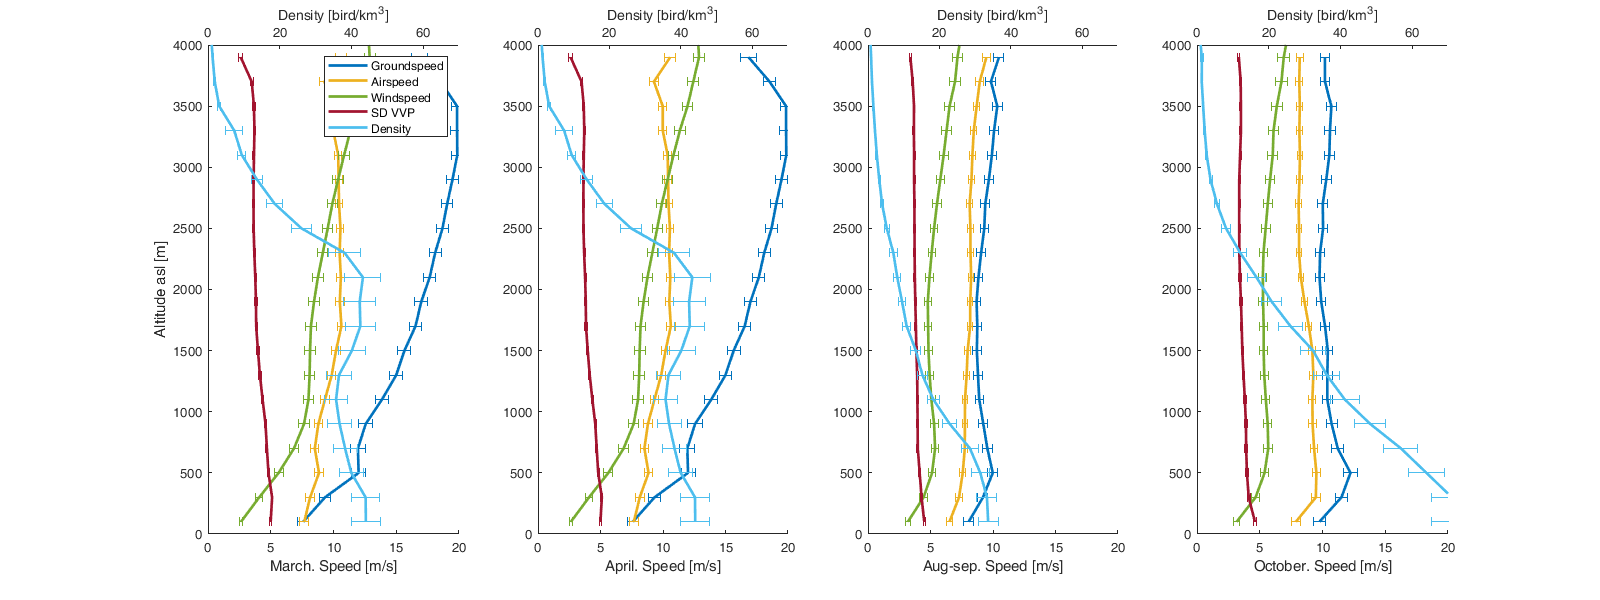

Mg = nan(numel(dc(1).alt),4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_esp,i_a,:),dens(id_esp,i_a,:));
    [~,~,Mg(i_a,3), Sg(i_a,3)] = histvdens(v_g(id_eau,i_a,:),dens(id_eau,i_a,:));
    [~,~,Ma(i_a,3), Sa(i_a,3)] = histvdens(v_a(id_eau,i_a,:),dens(id_eau,i_a,:));
    [~,~,Mw(i_a,3), Sw(i_a,3)] = histvdens(v_w(id_eau,i_a,:),dens(id_eau,i_a,:));
    [~,~,Ms(i_a,3), Ss(i_a,3)] = histvdens(sd_vvp(id_eau,i_a,:),dens(id_eau,i_a,:));
    [~,~,Md(i_a,3), Sd(i_a,3)] = histvdens(dens(id_eau,i_a,:),dens(id_eau,i_a,:));
    [~,~,Mg(i_a,4), Sg(i_a,4)] = histvdens(v_g(id_lau,i_a,:),dens(id_lau,i_a,:));
    [~,~,Ma(i_a,4), Sa(i_a,4)] = histvdens(v_a(id_lau,i_a,:),dens(id_lau,i_a,:));
    [~,~,Mw(i_a,4), Sw(i_a,4)] = histvdens(v_w(id_lau,i_a,:),dens(id_lau,i_a,:));
    [~,~,Ms(i_a,4), Ss(i_a,4)] = histvdens(sd_vvp(id_lau,i_a,:),dens(id_lau,i_a,:));
    [~,~,Md(i_a,4), Sd(i_a,4)] = histvdens(dens(id_lau,i_a,:),dens(id_lau,i_a,:));
end

figure('position',[0 0 1600 600]);
subplot(1,4,1); hold on;
tmp = errorbar(Mg(:,1),dc(1).alt,Sg(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,1),dc(1).alt,Sa(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,1),dc(1).alt,Sw(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,1),dc(1).alt,Ss(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
xlim([0 20]);ylabel('Altitude asl [m]'); xlabel('March. Speed [m/s]'); ylim([0 4000]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,1),dc(1).alt,Sd(:,1)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 70]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(1,4,2); hold on;
tmp = errorbar(Mg(:,2),dc(1).alt,Sg(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,2),dc(1).alt,Sa(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,2),dc(1).alt,Sw(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,2),dc(1).alt,Ss(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([0 20]); xlabel('April. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,2),dc(1).alt,Sd(:,2)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 70])

subplot(1,4,3); hold on;
tmp = errorbar(Mg(:,3),dc(1).alt,Sg(:,3)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,3),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,3),dc(1).alt,Sa(:,3)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,3),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,3),dc(1).alt,Sw(:,3)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,3),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,3),dc(1).alt,Ss(:,3)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,3),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([0 20]); xlabel('Aug-sep. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,3),dc(1).alt,Sd(:,3)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,3),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 70])

subplot(1,4,4); hold on;
tmp = errorbar(Mg(:,4),dc(1).alt,Sg(:,4)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,4),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,4),dc(1).alt,Sa(:,4)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,4),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,4),dc(1).alt,Sw(:,4)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,4),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,4),dc(1).alt,Ss(:,4)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,4),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([0 20]); xlabel('October. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,4),dc(1).alt,Sd(:,4)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,4),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 70])

**Local Functions**

function [e,h,M,S] = histvdens(v,dens,bin,norm)
    if ~exist('bin','var'), bin = 200; end
    if ~exist('norm','var'), norm = true; end
    id = ~isnan(v)&~isnan(dens);
    if sum(id(:))==0
        e=[];
        h=[];
        M=NaN;
        S=NaN;        
    else
        [Y,edge] = discretize(v(id),bin); 
        [G,ID] = findgroups(Y);
        h=zeros(numel(edge)-1,1);
        h(ID) = splitapply(@sum, dens(id), G);    
        e = 0.5 * (edge(1:end-1) + edge(2:end));
        M = nansum(v(id).*dens(id))/nansum(dens(id));
        S = nanstd(v(id & dens>0),dens(id & dens>0));
        if norm, h=h./nansum(h); end
    end
end